## Paralelización del método de Jacobi para sistemas lineales 

`Jacobi secuencial vs. paralelo`

`Sección 1: validación con un sistema pequeño.`

`Sección 2: experimentos de tiempo, aceleración y eficiencia.`

`Sección 3: tablas y gráficas.`

clear; clc; close all;

maxNumCompThreads(1);     % el cliente usa un solo hilo: T_1 es realmente secuencial

tol      = 1e-10;         % tolerancia sobre R_k
max_iter = 500;
semilla  = 2026;

%% 1. Validación con un sistema pequeño
n = 500;
[A, b, x_exacta] = generar_sistema(n, semilla);
x0 = zeros(n, 1);

[x_s, it_s, res_s] = jacobi_seq(A, b, x0, tol, max_iter);
[x_v, it_v, res_v] = jacobi_vec(A, b, x0, tol, max_iter);

delete(gcp('nocreate'));
parpool("Threads", 4);

Starting parallel pool (parpool) using the 'Threads' profile ...
Connected to parallel pool with 4 workers.


[x_p, it_p, res_p] = jacobi_par(A, b, x0, tol, max_iter);
delete(gcp('nocreate'));

Parallel pool using the 'Threads' profile is shutting down.



fprintf('--- Validación (n = %d) ---\n', n);

--- Validación (n = 500) ---


fprintf('Iteraciones:     seq = %d, vec = %d, par = %d\n', it_s, it_v, it_p);

Iteraciones:     seq = 34, vec = 34, par = 34


fprintf('Residuo final:   seq = %.2e, vec = %.2e, par = %.2e\n', ...
    res_s(end), res_v(end), res_p(end));

Residuo final:   seq = 5.20e-11, vec = 5.20e-11, par = 5.20e-11


fprintf('Error relativo vs. solución exacta: %.2e\n', ...
    norm(x_s - x_exacta) / norm(x_exacta));

Error relativo vs. solución exacta: 5.20e-11


fprintf('||x_seq - A\\b|| / ||A\\b|| = %.2e\n', norm(x_s - A\b) / norm(A\b));

||x_seq - A\b|| / ||A\b|| = 5.20e-11


fprintf('||x_par - x_seq||        = %.2e\n', norm(x_p - x_s));

||x_par - x_seq||        = 0.00e+00


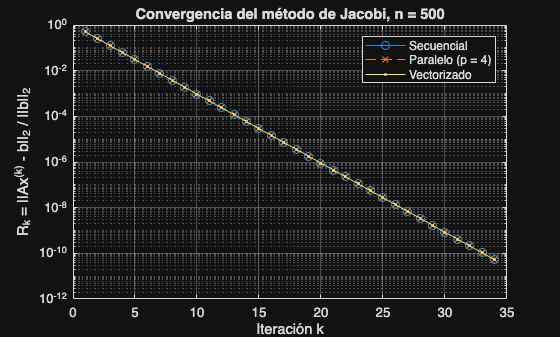


figure;
semilogy(res_s, 'o-'); hold on;
semilogy(res_p, 'x--');
semilogy(res_v, '.-');
xlabel('Iteración k');
ylabel('R_k = ||Ax^{(k)} - b||_2 / ||b||_2');
legend('Secuencial', 'Paralelo (p = 4)', 'Vectorizado', 'Location', 'northeast');
title(sprintf('Convergencia del método de Jacobi, n = %d', n));
grid on;

%% 2. Experimentos de tiempo
lista_n = [500 1000 2000 4000 6000 8000 10000];
lista_p = [1 2 4 6 8];
reps    = 3;              % se reporta la mediana de las repeticiones

resultados  = [];
tiempo_pool = [];
x_ref = cell(size(lista_n));

% 2a. Versiones secuencial y vectorizada
for a = 1:numel(lista_n)
    n = lista_n(a);
    [A, b] = generar_sistema(n, semilla);
    x0 = zeros(n, 1);

    [t, x, it, res] = medir(@() jacobi_seq(A, b, x0, tol, max_iter), reps);
    x_ref{a} = x;
    resultados = [resultados; fila(n, "secuencial", 1, t, it, res(end), 0)]; %#ok<AGROW>

    [t, x, it, res] = medir(@() jacobi_vec(A, b, x0, tol, max_iter), reps);
    resultados = [resultados; fila(n, "vectorizado", 1, t, it, res(end), ...
        norm(x - x_ref{a}))]; %#ok<AGROW>

    fprintf('n = %5d listo (secuencial y vectorizado)\n', n);
end

n =   500 listo (secuencial y vectorizado)
n =  1000 listo (secuencial y vectorizado)
n =  2000 listo (secuencial y vectorizado)
n =  4000 listo (secuencial y vectorizado)
n =  6000 listo (secuencial y vectorizado)
n =  8000 listo (secuencial y vectorizado)
n = 10000 listo (secuencial y vectorizado)



% 2b. Versión paralela para cada número de workers
for p = lista_p
    delete(gcp('nocreate'));
    tic;
    parpool("Threads", p);
    tiempo_pool = [tiempo_pool; table(p, toc, ...
        'VariableNames', {'p', 'arranque_pool_s'})]; %#ok<AGROW>

    % Calentamiento: la primera llamada a parfor tiene un costo extra
    [A, b] = generar_sistema(50, semilla);
    jacobi_par(A, b, zeros(50, 1), tol, 5);

    for a = 1:numel(lista_n)
        n = lista_n(a);
        [A, b] = generar_sistema(n, semilla);
        x0 = zeros(n, 1);

        [t, x, it, res] = medir(@() jacobi_par(A, b, x0, tol, max_iter), reps);
        resultados = [resultados; fila(n, "paralelo", p, t, it, res(end), ...
            norm(x - x_ref{a}))]; %#ok<AGROW>

        fprintf('p = %d, n = %5d listo\n', p, n);
    end
end

Starting parallel pool (parpool) using the 'Threads' profile ...
Connected to parallel pool with 1 workers.


p = 1, n =   500 listo
p = 1, n =  1000 listo
p = 1, n =  2000 listo
p = 1, n =  4000 listo
p = 1, n =  6000 listo
p = 1, n =  8000 listo
p = 1, n = 10000 listo


Parallel pool using the 'Threads' profile is shutting down.


Starting parallel pool (parpool) using the 'Threads' profile ...
Connected to parallel pool with 2 workers.


p = 2, n =   500 listo
p = 2, n =  1000 listo
p = 2, n =  2000 listo
p = 2, n =  4000 listo
p = 2, n =  6000 listo
p = 2, n =  8000 listo
p = 2, n = 10000 listo


Parallel pool using the 'Threads' profile is shutting down.


Starting parallel pool (parpool) using the 'Threads' profile ...
Connected to parallel pool with 4 workers.


p = 4, n =   500 listo
p = 4, n =  1000 listo
p = 4, n =  2000 listo
p = 4, n =  4000 listo
p = 4, n =  6000 listo
p = 4, n =  8000 listo
p = 4, n = 10000 listo


Parallel pool using the 'Threads' profile is shutting down.


Starting parallel pool (parpool) using the 'Threads' profile ...
Connected to parallel pool with 6 workers.


p = 6, n =   500 listo
p = 6, n =  1000 listo
p = 6, n =  2000 listo
p = 6, n =  4000 listo
p = 6, n =  6000 listo
p = 6, n =  8000 listo
p = 6, n = 10000 listo


Parallel pool using the 'Threads' profile is shutting down.


Starting parallel pool (parpool) using the 'Threads' profile ...
Connected to parallel pool with 8 workers.


p = 8, n =   500 listo
p = 8, n =  1000 listo
p = 8, n =  2000 listo
p = 8, n =  4000 listo
p = 8, n =  6000 listo
p = 8, n =  8000 listo
p = 8, n = 10000 listo


delete(gcp('nocreate'));

Parallel pool using the 'Threads' profile is shutting down.



%% 3. Aceleración, eficiencia y gráficas
sec = resultados(resultados.version == "secuencial", :);
par = resultados(resultados.version == "paralelo", :);

par.T1 = zeros(height(par), 1);
for k = 1:height(par)
    par.T1(k) = sec.tiempo_s(sec.n == par.n(k));
end
par.Sp  = par.T1 ./ par.tiempo_s;
par.eta = par.Sp ./ par.p;

writetable(resultados,  'resultados.csv');
writetable(par,         'aceleracion.csv');
writetable(tiempo_pool, 'tiempo_pool.csv');
disp(par(:, {'n', 'p', 'tiempo_s', 'Sp', 'eta', 'iteraciones', 'dif_vs_seq'}));

      n      p    tiempo_s       Sp          eta       iteraciones    dif_vs_seq
    _____    _    ________    ________    _________    ___________    __________

      500    1    0.057718     0.25497      0.25497        34             0     
     1000    1    0.099087     0.33774      0.33774        34             0     
     2000    1     0.27621     0.49247      0.49247        34             0     
     4000    1     0.80475     0.67176      0.67176        34             0     
     6000    1       1.796     0.70133      0.70133        34             0     
     8000    1      2.8313     0.77004      0.77004        34             0     
    10000    1      4.7693     0.82278      0.82278        34             0     
      500    2    0.079343     0

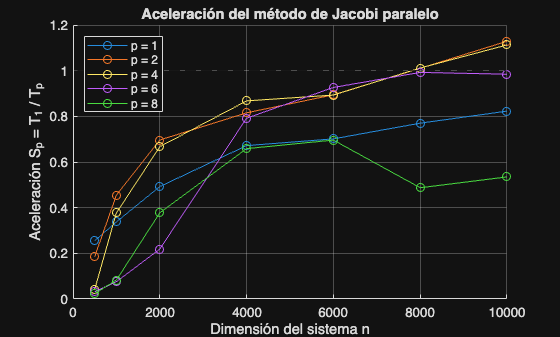


figure; hold on;
for p = lista_p
    sel = par.p == p;
    plot(par.n(sel), par.Sp(sel), 'o-', 'DisplayName', sprintf('p = %d', p));
end
yline(1, 'k--', 'HandleVisibility', 'off');
xlabel('Dimensión del sistema n');
ylabel('Aceleración S_p = T_1 / T_p');
title('Aceleración del método de Jacobi paralelo');
legend('Location', 'northwest'); grid on;

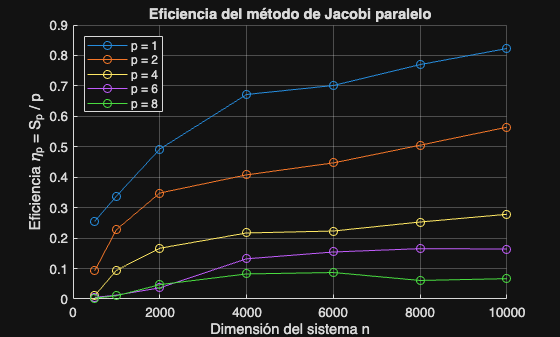


figure; hold on;
for p = lista_p
    sel = par.p == p;
    plot(par.n(sel), par.eta(sel), 'o-', 'DisplayName', sprintf('p = %d', p));
end
xlabel('Dimensión del sistema n');
ylabel('Eficiencia \eta_p = S_p / p');
title('Eficiencia del método de Jacobi paralelo');
legend('Location', 'northwest'); grid on;